# **1 - OPTION PRICING**

## SETUP

% Initialize workspace
clc; clear; close all;

% Fix randomness
rng('default');   

% Add shared library folder
addpath(genpath(fullfile('..','..','lib')));

% Add project-specific folders
addpath(genpath('src'));
addpath(genpath('data'));
addpath(genpath('results'));

% Define paths
resultsPath = fullfile('results');
figuresPath = fullfile('results', 'figures');
srcPath = fullfile('src');
dataRawPath = fullfile('data', 'raw');
dataInterimPath = fullfile('data', 'interim');
dataProcessedPath = fullfile('data', 'processed');

## **EXERCISE 1**

**Price a European Call Option with the following characteristics: **

### UPLOAD DATA

% Load option parameters
load(fullfile(dataRawPath, 'params.mat'), 'params');

% Underlying future price
F0 = params.F0;
% Strike price
K = params.K;
% ttm
T = params.T;
% ttm zero rate
r = params.r;
% Volatility
sigma = params.sigma;
% Yield
q = params.q;
% Notional
N = params.N;
% Knock-In Barrier
KI = params.KI;

% Compute the discount factor
B = exp(-r*T);

% Set the flag:
% For European Call = +1
% For European Put  = -1
optionType = 1;

### **POINT A**

Price the option, considering an underlying price equal to 1 Euro (i.e a derivative Notional of 1 Mln Euro): 

- via blkprice Matlab function; 

- with a CRR tree approach; 

- with a Monte-Carlo (MC) approach. 

% 1.
optionPriceBLK = EuropeanOptionClosed(F0, K, B, T, sigma, optionType);

% 2.
nStep = 1e5;
optionPriceCRR = EuropeanOptionCRR(F0, K, B, T, sigma, nStep, optionType);

% 3.
nSim = 1e7;
[optionPriceMC, ~] = EuropeanOptionMC(F0, K, B, T, sigma, nSim, optionType);

% Display results
display(optionPriceBLK);

optionPriceBLK = 0.0435

display(optionPriceCRR);

optionPriceCRR = 0.0435

display(optionPriceMC);

optionPriceMC = 0.0435

### **POINT B**

Focus on a call. Select M according to the criteria discussed, consider M:

- as the number of intervals in CRR;

- as the number of simulations in the MC.

% 1.
TuneCRR(F0, K, B, T, sigma, optionType);

CRR steps: 128 
Black-76 Price: 0.0435 € 
CRR Price: 0.0434 € 
Error: 0.000085


% 2.
TuneMC(F0, K, B, T, sigma, optionType);

CRR steps: 524288 
Black-76 Price: 0.0435 € 
CRR Price: 0.0434 € 
Error: 0.000094


### **POINT C**

Show that the numerical errors for a call rescale with M:

-  as $\frac{1}{M}$ for CRR;

-  as $\frac{1}{\sqrt{M}}$ for MC. 

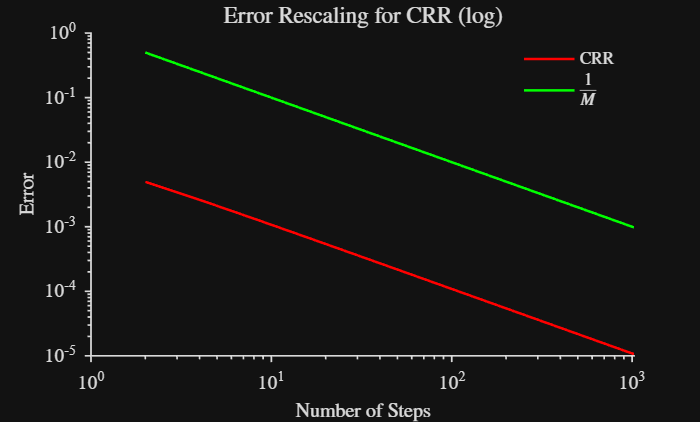

%% 1. 
[nStep, errCRR] = PlotErrorCRR(F0, K, B, T, sigma);

figCRR = figure;
loglog(nStep, errCRR, '-r', 'DisplayName', 'CRR'); hold on;
loglog(nStep, 1./nStep, '-g', 'DisplayName', '$\frac{1}{M}$');
PlotUtils.setStyle();
PlotUtils.setLabels('Number of Steps', 'Error', 'Error Rescaling for CRR (log)');
PlotUtils.setLegend('northeast'); 

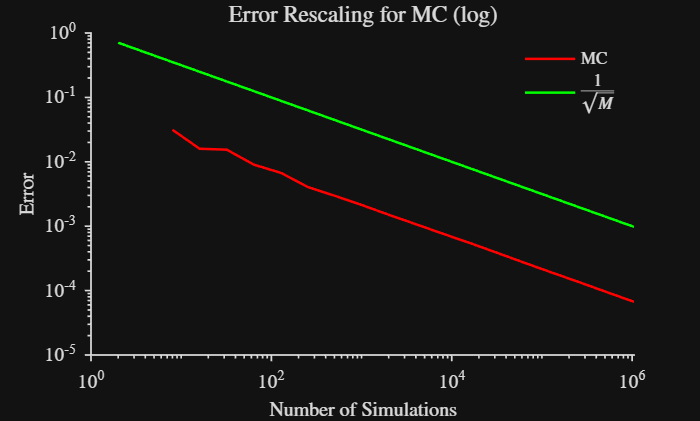

%% 2. 
[nSim, errMC] = PlotErrorMC(F0, K, B, T, sigma);

figMC = figure;
loglog(nSim, errMC, '-r', 'DisplayName', 'MC'); hold on;
loglog(nSim, 1./sqrt(nSim), '-g', 'DisplayName', '$\frac{1}{\sqrt{M}}$');
PlotUtils.setStyle();
PlotUtils.setLabels('Number of Simulations', 'Error', 'Error Rescaling for MC (log)');
PlotUtils.setLegend('northeast'); 

### POINT D

Price also a European Call Option with European barrier at 1.3 € (up&in) and same parameters with:

- closed formula;

- the two numerical techniques (CRR  & MC)..

% 1.
optionpriceBLK = EuropeanOptionClosedKI(F0, K, KI, B, T, sigma);

% 2.
nStep = 1e4;
optionPriceMC = EuropeanOptionKIMC(F0, K, KI, B, T, sigma, nStep);
optionPriceCRR = EuropeanOptionKICRR(F0, K, KI, B, T, sigma, nStep);

% Display results
display(optionpriceBLK);
display(optionPriceMC);
display(optionPriceCRR);

### POINT E

For this barrier option, plot the Vega (possibly using both the closed formula and a numerical estimate) with the underlying price in the range 0.70 Euro and 1.5 Euro.

### POINT F

Does antithetic variables technique reduce MC error of question B? 

### POINT G

Price also, with the Tree, a Bermudan option, where the holder has also the right to exercise the option at the end of every month, obtaining the stock at the strike price. 

### POINT H

Pricing the Bermudan option, vary the dividend yield between 0% and 6% and compare with the corresponding European price.